# TD7 calculs symboliques

clearvars
syms z w N
assume(N>1)


Calcul des zéros et pôles de $H(z)$

H(z)= 1/N *(1-z^(-N))/(1-z^(-1))

$$H(z) = \frac{\frac{1}{z^{N}}-1}{N\,\left(\frac{1}{z}-1\right)}$$

eqn1=H(z)==0

$$eqn1 = \frac{\frac{1}{z^{N}}-1}{N\,\left(\frac{1}{z}-1\right)}=0$$

eqn1=simplify(eqn1)

$$eqn1 = \frac{1}{z^{N}}=1$$

[zeros,parameters,conditions] = solve(eqn1,z,'ReturnConditions',true)

$$zeros = {\mathrm{e}}^{\frac{2\,\pi \,k\,\mathrm{i}}{N}}$$

$$parameters = k$$

$$conditions = k\in \mathbb{Z}\wedge -\frac{N}{2}<k\wedge k\leq \frac{N}{2}$$


eqn2= 1/H(z)== 0

$$eqn2 = \frac{N\,\left(\frac{1}{z}-1\right)}{\frac{1}{z^{N}}-1}=0$$

eqn2=simplify(eqn2)

$$eqn2 = z=1$$

poles = solve(eqn2,z)

$$poles = 1$$

Calcul du module de  $H(e^{j\omega})$ pour une valeur particulière de N 

H=subs(H,z,exp(j*w))

$$H(z) = \frac{\frac{1}{{\left({\mathrm{e}}^{w\,\mathrm{i}}\right)}^{N}}-1}{N\,\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}$$

assume(w,'real')
H=subs(H,N,4) % instantiation de N =2 N=4 N=6 etc ...

$$H(z) = \frac{{\mathrm{e}}^{-4\,w\,\mathrm{i}}-1}{4\,\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}$$

H=simplify(H)

$$H(z) = \frac{{\mathrm{e}}^{-4\,w\,\mathrm{i}}-1}{4\,\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}$$

modH=sqrt(real(H)^2+imag(H)^2)

$$modH(z) = \begin{array}{l} \sqrt{{\left(\frac{\sin\left(4\,w\right)\,\sin\left(w\right)}{\sigma_{1}}+\frac{\left(\cos\left(w\right)-1\right)\,\left(\cos\left(4\,w\right)-1\right)}{\sigma_{1}}\right)}^{2}+{\left(\frac{\sin\left(4\,w\right)\,\left(\cos\left(w\right)-1\right)}{\sigma_{1}}-\frac{\sin\left(w\right)\,\left(\cos\left(4\,w\right)-1\right)}{\sigma_{1}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=4\,\left({\sin\left(w\right)}^{2}+{\left(\cos\left(w\right)-1\right)}^{2}\right) \end{array}$$

simplify(modH)

$$ans(z) = \frac{\sqrt{2}\,\left|\cos\left(w\right)\right|\,\sqrt{\cos\left(w\right)+1}}{2}$$

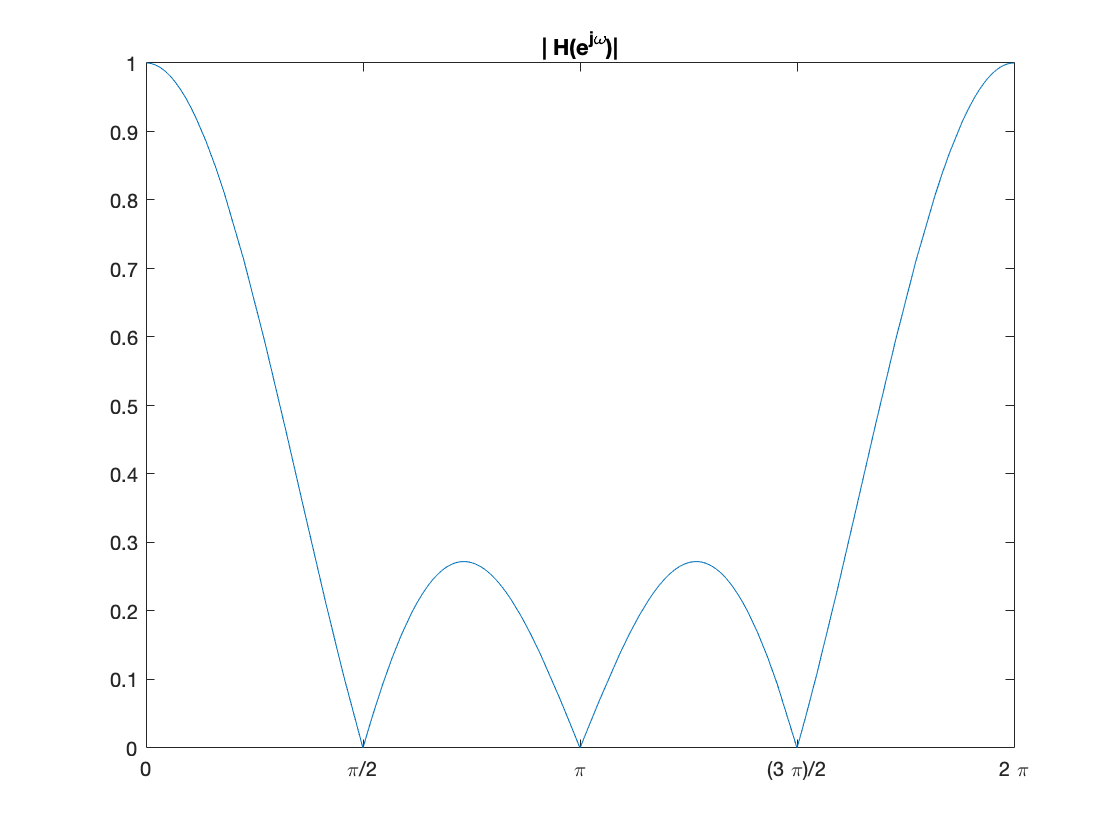

fplot(modH(w),[0 2*pi])
ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));     % graduation pour fonction trigo
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
title('| H(e^{j\omega})|')